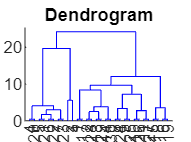


dub_MelCA1(isnan(dub_MelCA1)) = 0;

% Perform hierarchical clustering
tree = linkage(dub_MelCA1', 'ward', 'euclidean');

% Visualize dendrogram to determine the number of clusters
figure;
dendrogram(tree);
title('Dendrogram');


% Choose the number of clusters using the elbow method
inconsistent = inconsistent(tree);

Array indices must be positive integers or logical values.

inconsistent appears to be both a function and a variable. If this is unintentional, use 'clear inconsistent' to remove the variable 'inconsistent' from the workspace.

[~,~,~,best_k] = evalclusters(dub_MelCA1', 'linkage', 'silhouette', 'KList', 1:10);

% Extract cluster centroids as initial codebook vectors
k = best_k;
clusters = cluster(tree, 'maxclust', k);
initial_codebook = zeros(size(dub_MelCA1, 1), k);
for i = 1:k
    cluster_indices = find(clusters == i);
    initial_codebook(:, i) = mean(dub_MelCA1(:, cluster_indices), 2);
end

% Perform k-means clustering using initial codebook vectors
[idx, codebook] = kmeans(dub_MelCA1', k, 'Start', initial_codebook', 'MaxIter', 1000);

% Evaluate the performance of the clustering using silhouette plots
silhouette_values = silhouette(dub_MelCA1', idx);

% Plot silhouette values
figure;
silhouette(dub_MelCA1', idx);
title('Silhouette Plot');

% Display the resulting codebook
disp('Codebook:');
disp(codebook);


% Assume 'test_data' contains the testing data (each column represents a data point)
% Assume 'codebook' contains the codebook vectors (each column represents a codebook vector)

% Calculate distances between test data and codebook vectors
distances = pdist2(MelCA2', codebook', 'euclidean'); % Euclidean distance

% Assign labels based on nearest codebook vector
[~, assigned_labels] = min(distances, [], 2);

% If you have ground truth labels for evaluation
% Assume 'true_labels' contains the ground truth labels for the testing data
accuracy = sum(assigned_labels == true_labels) / length(true_labels);
disp(['Accuracy: ', num2str(accuracy)]);
